clear;

Astart = zeros([5 5 3]);
Adir = zeros([5 5 3]);
Bstart = zeros([5 5 3]);
Bdir = zeros([5 5 3]);
        
for y = 1:5
    for x = 1:5
        Astart(y, x, :) = [0.0 0.0 0.0];
        Adir(y, x, :) = [1.0 1.0 0.0];
        Bstart(y, x, :) = [0.5 0.0 0.5];
        Bdir(y, x, :) = [0.0 1.0 0.0];
    end
end

Astart(1, 2, :) = [0.0 0.0 0.0];
Adir(1, 2, :) = [0.5 0.1 0.1]; % Red diffuse.
Bstart(1, 2, :) = [0.8 0.5 0.5]; % Red-white total.
Bdir(1, 2, :) = [-0.15 -0.25 -0.2];

% Plotting only.
A1 = Astart(1, 1, :) + Adir(1, 1, :) .* (0:1)';
B1 = Bstart(1, 1, :) + Bdir(1, 1, :) .* (0:1)';

A2 = Astart(1, 2, :) + Adir(1, 2, :) .* (0:3)';
B2 = Bstart(1, 2, :) + Bdir(1, 2, :) .* (0:3)';

Astart = gpuArray(Astart);
Adir = gpuArray(Adir);
Bstart = gpuArray(Bstart);
Bdir = gpuArray(Bdir);

[Cstart, Cend, Cstartcoef, Cendcoef] = solveparallelline(Astart, Adir, Bstart, Bdir);

Cstart = gather(Cstart);
Cend = gather(Cend);

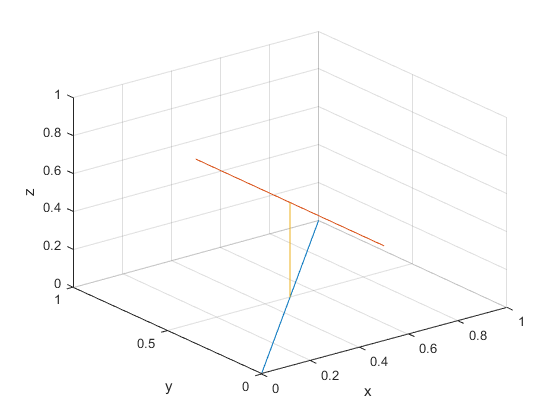

Cdir = Cend - Cstart;
C1 = Cstart(1, 1, :) + Cdir(1, 1, :) .* (0:1)';
C2 = Cstart(1, 2, :) + Cdir(1, 2, :) .* (0:1)';

plot3(A1(:, 1), A1(:, 2), A1(:, 3), ...
    B1(:, 1), B1(:, 2), B1(:, 3), ...
    C1(:, 1), C1(:, 2), C1(:, 3));

xlabel('x');
ylabel('y');
zlabel('z');
xlim([0.0 1.0]) ;
ylim([0.0 1.0]);
zlim([0.0 1.0]);
grid on;

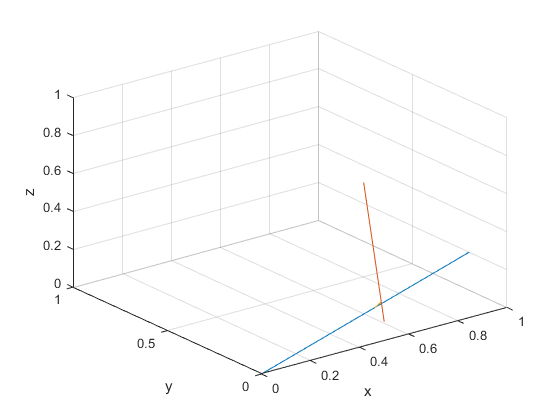


plot3(A2(:, 1), A2(:, 2), A2(:, 3), ...
    B2(:, 1), B2(:, 2), B2(:, 3), ...
    C2(:, 1), C2(:, 2), C2(:, 3));

xlabel('x');
ylabel('y');
zlabel('z');
xlim([0.0 1.0]) ;
ylim([0.0 1.0]);
zlim([0.0 1.0]);
grid on;


% Cstart on A, Cend on B.